# Gauß-Newton-Verfahren

Wir betrachten folgendes  nichtlineares Ausgleichsproblem:

           
$$\min_{z \in \mathbb{R}^3} \|F(z)\|_2,
$$


          $F_i(z):=\sqrt{(x_i-z_1)^2+(y_i-z_2)^2}-z_3 ~~i=1,\ldots, 40$,

mit Daten $(x_i,y_i)$, $i=1,\ldots,40$.

Falls $F_i(z)=0$ gilt, liegt $(x_i,y_i)$ auf dem Kreis mit Mittelpunkt $(z_1,z_2)$ und Radius $z_3$.

Wir betrachten einen Datensatz, der über Störungen von Punkten auf dem Kreis mit Mittelpunkt $(1,0)$ und Radius $1.5$ erzeugt wird. Die Größe der Störungen (aus einer gleichmäßigen Verteilung) wird über einen Parameter $\delta \in (0,0.5]$ gesteuert.  

Wahl von $\delta$-Wert:

delta=0.2;

Erzeugung der Daten:

h=2*pi/40;
rx=delta*(-1+2.*rand(40,1));
ry=delta*(-1+2.*rand(40,1));
x=zeros(40,1);
y=zeros(40,1);
for i=1:40
    x(i)=1+1.5*cos(i*h)+rx(i);
    y(i)=1.5*sin(i*h)+ry(i);
end

Als Startwert für das Gauss-Newton Verfahren  wählen wir

zold=[2, 1, 3]';

In jedem Iterationsschritt des Gauss-Newton-Verfahrens werden folgende Größen angezeigt:

- NormF$=\|F(z^k)\|_2$

- err$=\|\nabla \phi(z^k)\|_2$   (siehe Buch)

- KonvFaktor$=\|\nabla \phi(z^k)\|_2/\|\nabla \phi (z^{k-1})\|_2 $

Als Stoppkriterium wird verwendet:  err $\leq 10^{-6}$ oder $k  \geq k_{\max}=20$.

Falls mit höchstens 20 Iterationen die vorgebene Toleranz erreicht wird, werden $k$ (Anzahl der Iterationen) und $z^k$ (berechnete optimale Parameterwerte) gezeigt, und der diesen Parameterwerten entsprechende Kreis geplottet.

# Aktivität:

Sie können die Größe der Datenstörung und den Startvektor ändern und die dadurch entstehenden Effekte beobachten.

## Gauss-Newton-Verfahren:

k=0; kmax=20; epsilon=10^(-6);
err=1;
Fvalue=F(zold,x,y);
A=DF(zold,x,y);
errold=norm(A'*Fvalue);
Erg= zeros(2,kmax+1);
Erg(:,1)= [errold; norm(Fvalue)];
while ((k < kmax) && (err > epsilon))
    s=A\(-Fvalue); %lineares Ausgleichsproblem min_{s}\|As +Fvalue\|_2  wird gelöst
    znew=zold+s;
    Fvalue=F(znew,x,y);
    fprintf('\nIteration %u:', k+1);
    NormF=norm(Fvalue)
    A=DF(znew,x,y);
    err=norm(A'*Fvalue)
    KonvFaktor=err/errold
    disp('----------------');     
    errold=err;
    zold=znew;
    k=k+1;
    Erg(:,k+1)= [err; NormF];
end


Iteration 1:

NormF = 4.5994

err = 28.6071

KonvFaktor = 0.6202

----------------



Iteration 2:

NormF = 0.7475

err = 1.1108

KonvFaktor = 0.0388

----------------



Iteration 3:

NormF = 0.7261

err = 0.0038

KonvFaktor = 0.0034

----------------



Iteration 4:

NormF = 0.7261

err = 1.0134e-04

KonvFaktor = 0.0267

----------------



Iteration 5:

NormF = 0.7261

err = 2.7294e-06

KonvFaktor = 0.0269

----------------



Iteration 6:

NormF = 0.7261

err = 7.3508e-08

KonvFaktor = 0.0269

----------------


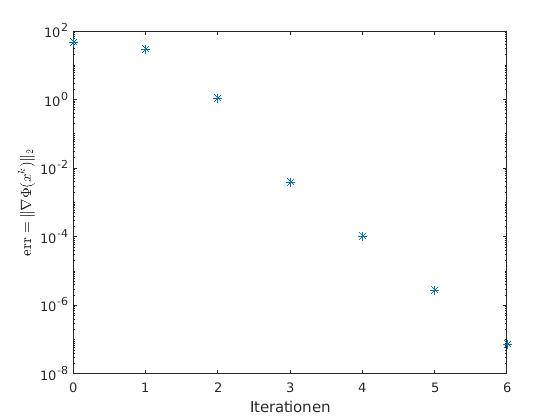

visualizeIter(Erg,k+1);


Toleranz erreicht nach k = 6 Iterationen 



 Optimale Parameterwerte für Mittelpunkt (z_1,z_2) und Radius z_3:

result =     1.0013
    0.0131
    1.4931


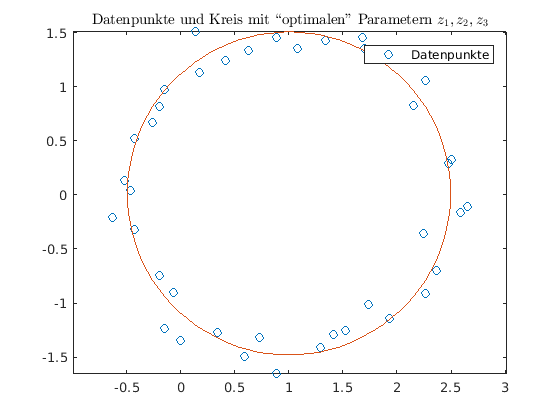


if (err > epsilon)
    fprintf('\n Toleranz nicht erreicht in 20 Iterationen \n');
else
    fprintf('\nToleranz erreicht nach k = %u Iterationen \n',k);
    fprintf('\n Optimale Parameterwerte für Mittelpunkt (z_1,z_2) und Radius z_3:');
    result=znew
    circle2(x,y, znew(1),znew(2),znew(3));
end

 In der Funktion `DF` wird die Jacobi-Matrix bestimmt.

function [DFout]=DF(z,x,y)
    DFout=zeros(40,3);
    for i=1:40
        DFout(i,1)=-(x(i)-z(1))/sqrt((x(i)-z(1))^2+(y(i)-z(2))^2);
        DFout(i,2)=-(y(i)-z(2))/sqrt((x(i)-z(1))^2+(y(i)-z(2))^2);
        DFout(i,3)=-1;
    end
end

In der Funktion `F` wird die Funktion $F$ ausgewertet. 

function [Fout]=F(z,x,y)
    Fout=zeros(40,1);
    for i=1:40
       Fout(i)=sqrt((x(i)-z(1))^2+(y(i)-z(2))^2)-z(3);
    end
end


Die Funktion `visualizeIter` plottet die Werte von err über die Iterationen $k$.

function visualizeIter(Erg,iter)
    semilogy(0:iter,Erg(1,1:iter+1),'*');
    xlabel('Iterationen');  ylabel('${\rm err}=\|\nabla \Phi(x^k)\|_2$','Interpreter','latex')
end

Die Funktion `circle2` wird verwendet, um den Kreis zu plotten.

function h = circle2(xd,yd,x,y,r)
    th = 0:pi/50:2*pi;
    xunit = r * cos(th) + x;
    yunit = r * sin(th) + y;
    h = plot(xd, yd, 'o', xunit, yunit);
    axis equal;
    legend('Datenpunkte');
    title('Datenpunkte und Kreis mit ``optimalen" Parametern $z_1,z_2,z_3$','Interpreter','latex');
end